# Script pour identifier transfert function du moteur

## Definition du model avec Te=0.1

Te=0.1;

sortie=sim("model.slx"); %30 seg d'execution avec STEP=2.5

Simulation aborted

## Utilisation ident et recuperation des transfer fuctions

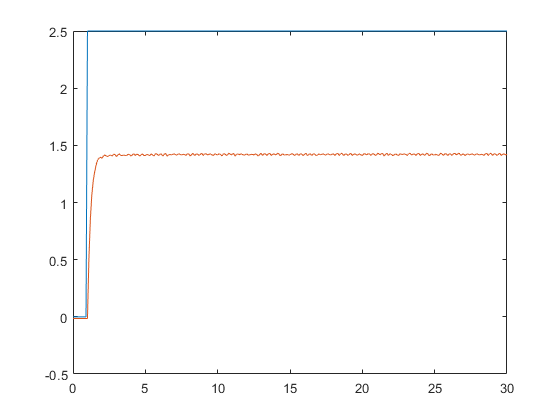

DataSortie=sortie.sortie.Data;
DataEntre=sortie.entre.Data;
Time=sortie.sortie.Time;
plot(Time,[DataEntre,DataSortie])

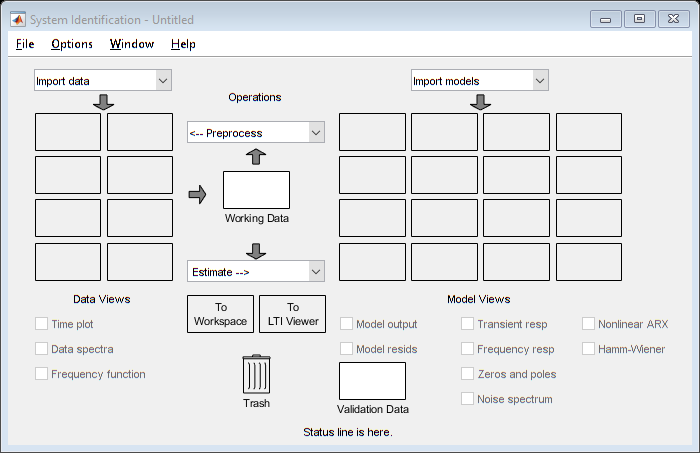

ident; % session saved in IdentStepMoteur.sid

## SBPA

%%Tf2 has best performance
G  = tf([tf2Step25.Numerator],[tf2Step25.Denominator]); %%Function trouve avant
S  = stepinfo(G);

N       = 5;
Tr      = S.SettlingTime*2;
Ts      = Tr/20;
P       = 4;
Plot    = 0;
[u1,t1] =prbs(Ts,N,Tr,P,Plot);
SBPA=[(t1'), u1];
SBPA=SBPA.*2.5;
 
% Execution du model avec SBPA

sor=sim("modelSBPA.slx") %30seg

sor =   Simulink.SimulationOutput:

              entreSPBA: [1x1 timeseries] 
             sortieSBPA: [1x1 timeseries] 
                   tout: [301x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Utilisation ident et recuperation de transfer fuctions

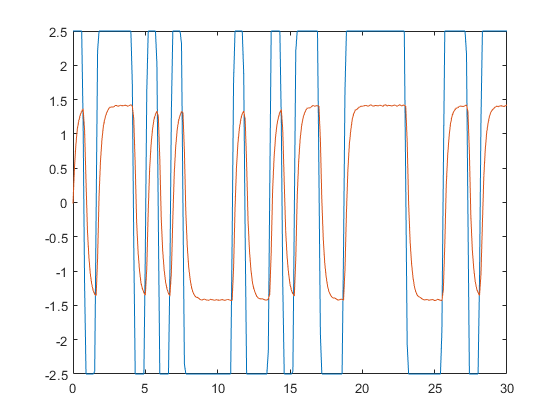

SBPASortie=sor.sortieSBPA.Data;
SBPAEntre=sor.entreSPBA.Data;
Time=sor.sortieSBPA.Time;

plot(Time,[SBPAEntre,SBPASortie])

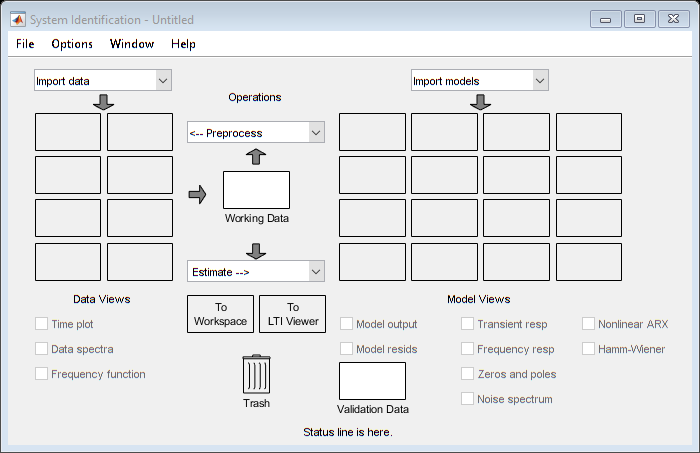

ident; % session saved in IdentSBPAMoteur.sid

%Gf=tf([tf2SBPA.Numerator],[tf2SBPA.Denominator])

## Discretitation des transfert fuctions

T=59; % Trouvé a TP4 moteur
K=4.68;

Kp=(2*T-Te)/(K*Te);

GzMain=tf([K],[T/Te (1-T/Te)],Te) %Transfert function calculee a la main (voir TP3)

GzMain =
 
     4.68
  -----------
  590 z - 589
 
Sample time: 0.1 seconds
Discrete-time transfer function.



GzStep= tf([tf2Step25.Numerator],[tf2Step25.Denominator],Te) %Transfert fuction ident/Step

GzStep =
 
    2.594
  ---------
  z + 4.569
 
Sample time: 0.1 seconds
Discrete-time transfer function.



GzSBPA=tf([tf2SBPA25.Numerator],[tf2SBPA25.Denominator],Te) %Transfert fuction ident/SBPA

GzSBPA =
 
    3.023
  ---------
  z + 5.379
 
Sample time: 0.1 seconds
Discrete-time transfer function.



GzSBPA1=tf([tf1SBPA25.Numerator],[tf1SBPA25.Denominator],Te) %deux poles et un zero

GzSBPA1 =
 
     3.739 z + 59.61
  ---------------------
  z^2 + 26.43 z + 105.2
 
Sample time: 0.1 seconds
Discrete-time transfer function.



## Analysis des transfert functions

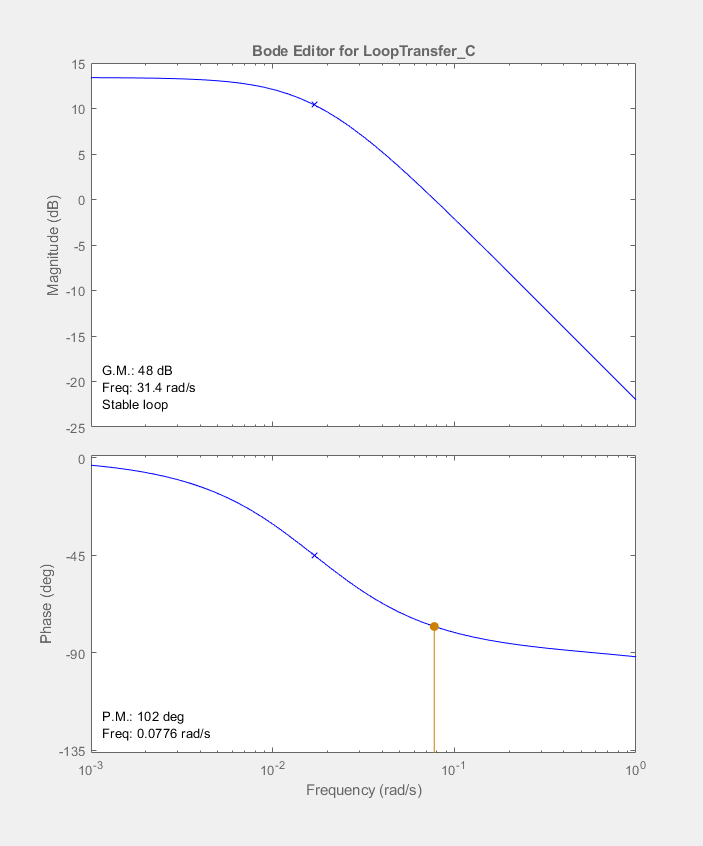

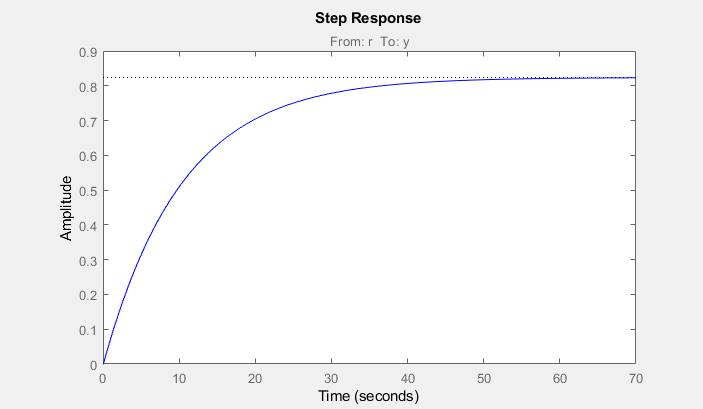

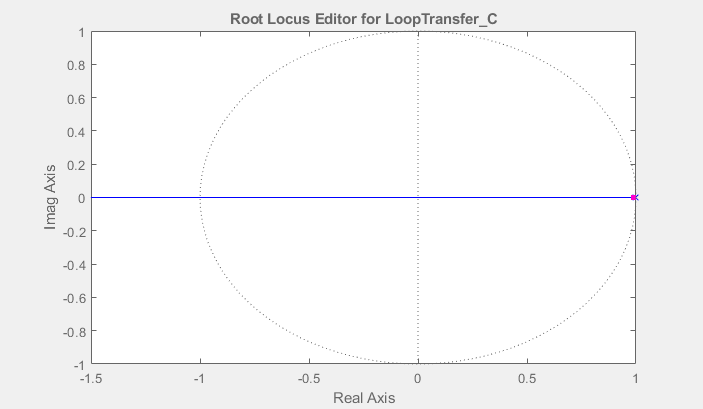

%1) Gzmain 
 sisotool(GzMain)

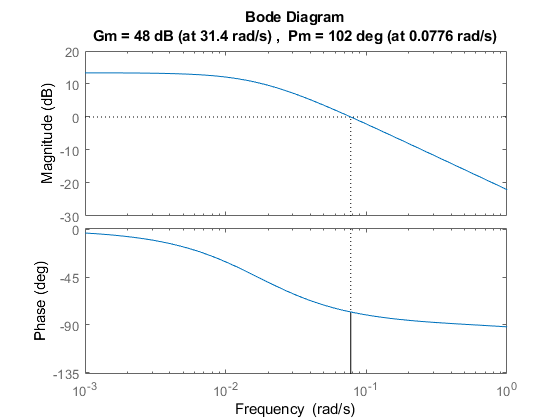

 margin(GzMain)

 %GM = 48dB PM=102 
 P=pole(GzMain)

P = 0.9983

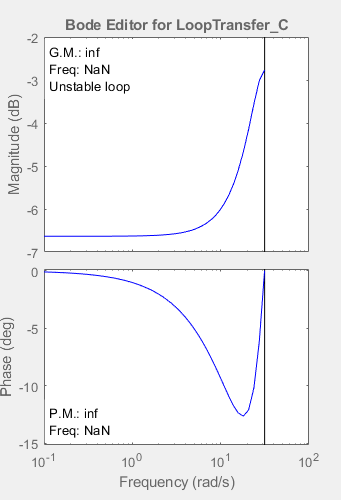

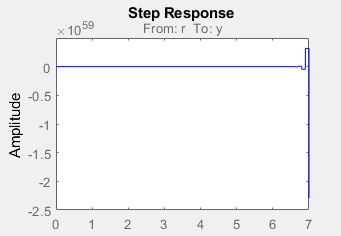

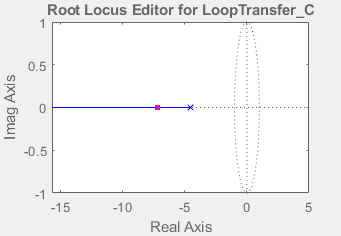

%2) GzStep
sisotool(GzStep)

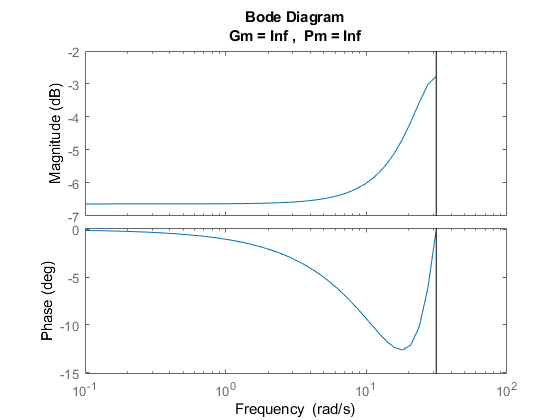

margin(GzStep)

P=pole(GzStep)

P = -4.5689

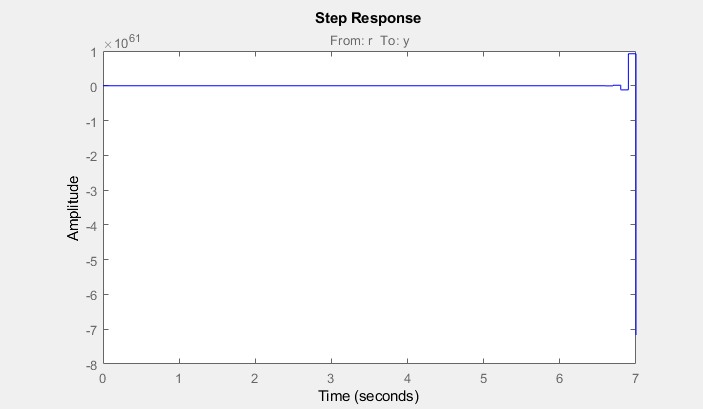

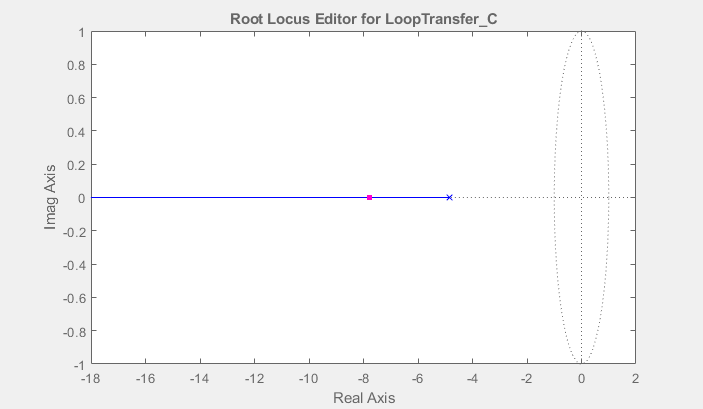

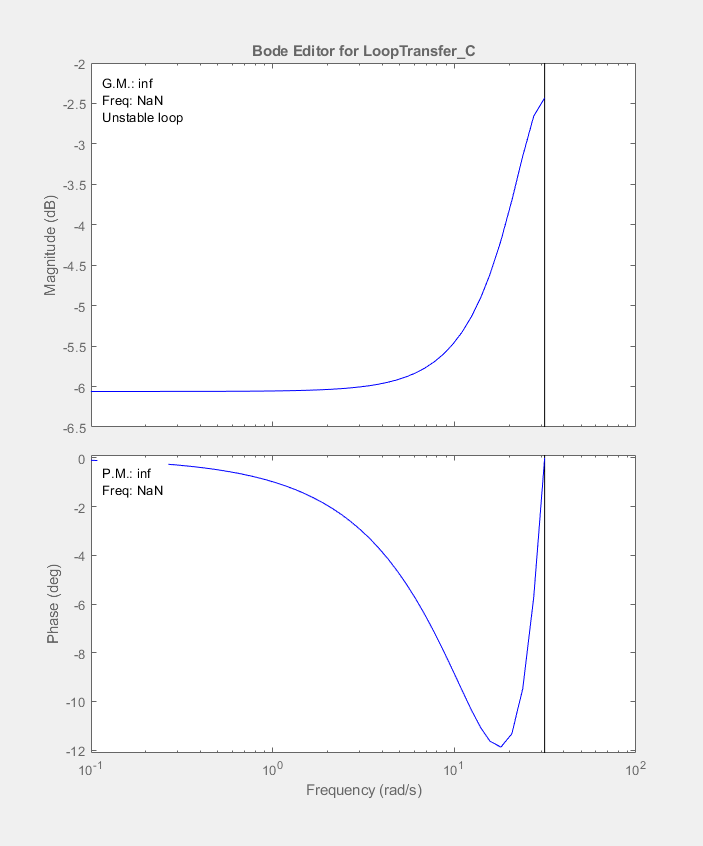

%3) GzSBPA
sisotool(GzSBPA)

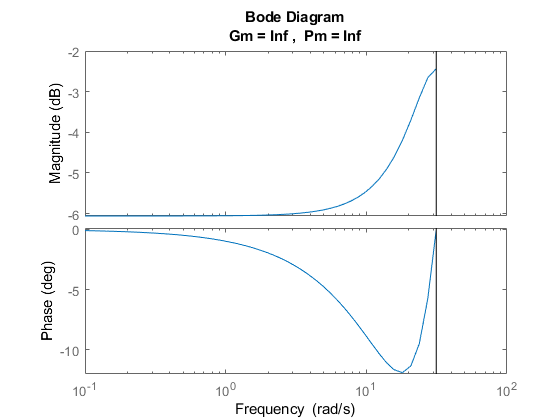

margin(GzSBPA)

P=pole(GzSBPA)

P = -4.8564

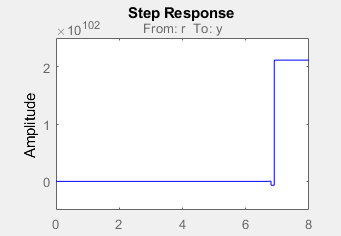

%4) GzSBPA1
sisotool(GzSBPA1)

margin(GzSBPA1)
P=pole(GzSBPA1)

P =   -27.9919
   -3.7464


## Correcteurs

%P, PI, PID
%P c'est pas possible pcq il y aurait un erreur statique constantes tjrs

%PI

%PI 1 Tuning PID avec 800ms response time 

PI1=tf([30.36 -0.8978*30.36],[1 -1],Te)

PI1 =
 
  30.36 z - 27.26
  ---------------
       z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% H=(PI1*GzMain)/(PI1*GzMain+1)
% margin(H)
% stepplot(H)

%PI 2 Tuning PID avec 600ms response time et plus agresive 
PI2=tf([27.258 -0.4569*27.258],[1 -1],Te)

PI2 =
 
  27.26 z - 12.45
  ---------------
       z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%PID 1 
PID1=tf([0.2755 -0.5487 0.2733],[1 -1.996 0.9963],Te) 

PID1 =
 
  0.2755 z^2 - 0.5487 z + 0.2733
  ------------------------------
      z^2 - 1.996 z + 0.9963
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%PID 2 0.7 response time 0.3 robust

PID2=tf([16.18 0.8317 -15.35],[1 -1.121 0.1208],Te)

PID2 =
 
  16.18 z^2 + 0.8317 z - 15.35
  ----------------------------
     z^2 - 1.121 z + 0.1208
 
Sample time: 0.1 seconds
Discrete-time transfer function.

